# Chaos

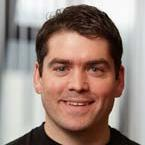

**Dr Jon Shiach**

**Department of Computing and Mathematics**

**Email:** j.shiach@mmu.ac.uk 

## Introduction

## Differential equations

### Differentials

Consider the graph of the curve of $y = f(x)$ below where $f$ is some function of $x$. 

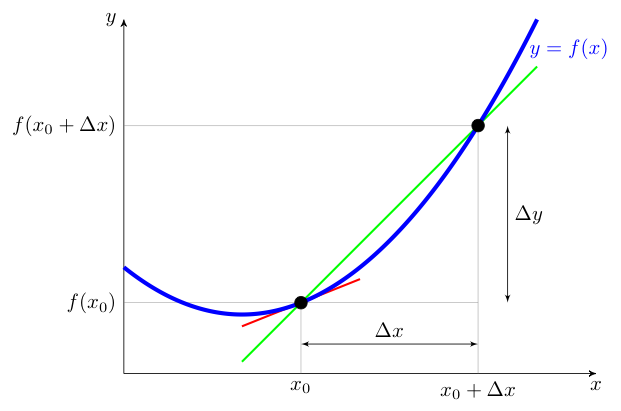

Lets say we want to calculate the gradient (or steepness) of the curve $y = f(x)$ at the point $x_0$ (denoted by the red line). The gradient of a line is calculated by dividing the change in the vertical direction, denoted by $\Delta y$, by the change in the horizontal direction, denoted by $\Delta x$, i.e.,


$$\text{gradient} = \frac{\Delta y}{\Delta x}.$$


So to calculate the gradient of the green line we have


$$\frac{\Delta y}{\Delta x} = \frac{f(x_0 + \Delta x) - f(x_0)}{\Delta x}.$$


Of course looking at the diagram we can clearly see that the red and green lines have different gradients. However, if we reduce the value of $\Delta x$ so that the two points $x_0$ and $x_0 + \Delta x$ are very close together then the gradients of the two lines will be very similar. We can write this mathematically as


$$\text{gradient} = \lim_{\Delta x \to 0} \frac{\Delta y}{\Delta x}.$$


This means "*what is the limit of the fraction as *$\Delta x$* gets close to *$0$*?*". To simplify the presentation we let $\mathrm{d}x$ and $\mathrm{d}y$ represent infinitely small changes in the values of $x$ and $y$  ($\mathrm{d}$ is used because $\Delta$ is the Greek character *delta* which corresponds to the Latin character *d*) so we write


$$\text{gradient} = \frac{\mathrm{d}y}{\mathrm{d}x}.$$


$\mathrm{d}x$ and $\mathrm{d}y$ are known as **differentials**, $\frac{\mathrm{d}y}{\mathrm{d}x}$ is known as the **derivative** of $y$ and the process of determining the derivative is known as **differentiation**. 

### Rate of change

A good way to think about differentials are in term of **the rate of change of one variable with respect to another**. Consider the velocity of an object moving along an $x$ axis which is calculated using


$$\text{velocity} = \frac{\text{distance travelled}}{\text{time taken}}.$$


So we can think of velocity as the change in the position, $x$, with respect to time, $t$, i.e.,


$$\text{velocity} = \frac{\mathrm{d}x}{\mathrm{d}t}.$$


Also, acceleration is the change in velocity with respect to time so


$$\text{acceleration} = \frac{\mathrm{d}u}{\mathrm{d}t}.$$


## Modelling the motion of a pendulum

We can use derivatives to produce a mathematical model of simple pendulum which is shown in the diagram below. A pendulum consists of weight that is suspended from a fixed point known as a pivot. When the pendulum is displaced to one side of the pivot and released, the force of gravity acting on the weight causes it to move back of forth underneath the pivot.

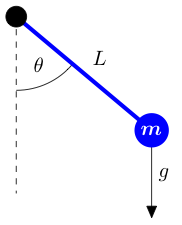

Here $m$ is the mass of the weight, $L$ is the length of the rod that connects the weight to the pivot, $\theta$ is the angle between the rod and the vertical and $g$ is the acceleration due to gravity (on Earth this is approximately equal to $9.81\text{ms}^{-2}$). Using Newton's second law of motion we can derive the following differential equations that model the motion of the pendulum


$$\begin{array}{ll}
\frac{\mathrm{d}\theta_1}{\mathrm{d}t} = \theta_2  & \text{(the velocity of the angle $\theta$)}, \\
    \frac{\mathrm{d}\theta_2}{\mathrm{d}t} = -\frac{g}{L} \sin(\theta_1) & \text{(the acceleration of the angle $\theta$)}.
\end{array}$$


The code below defines these differential equations that model the pendulum, defines the parameters that govern the pendulum before solving the differential equations and producing an animation of the pendulum.

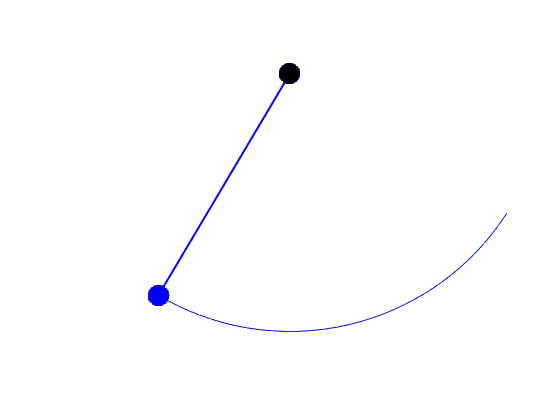

% Define pendulum parameters
L = 1;
theta = 1;
g = 9.81;
tmax = 5;

% Solve the differential equation
t = linspace(0, tmax, tmax * 60 + 1);
y0 = [theta, 0];
[t, y] = ode45(@(t, y)pendulum(t, y, L), t, y0);

% Calculate the (x, y) co-ordinates of the pendulum
x = L * sin(y(:, 1));
y = - L * cos(y(:, 1));

% Plot pendulum
plotpendulum(t, x, y)

Note that the pendulum oscillates back and forth and returns to the same initial starting point. Since there is not other forces such as friction or air resistance acting on the pendulum it will continue to move in this way forever.

### Modelling a double pendulum

We have seen that a single pendulum behaves in a regular and predictable way but what happens if we connect another pendulum to the single pendulum? Consider the diagram below of a double pendulum. The first pendulum has mass $m_1$, length $L_1$ and initial displacement angle $\theta_1$ and the second pendulum has mass $m_2$, length $L_2$ and initial displacement angle $\theta_2$.

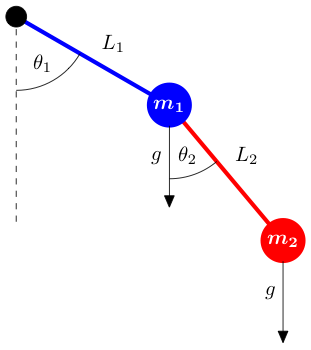

The differential equations that model the motion of the double pendulum as a bit more complicated than for the single pendulum so is not written here.

The code below solves the differential equations that models a double pendulum and produces an animation showing the motion of the pendulum.

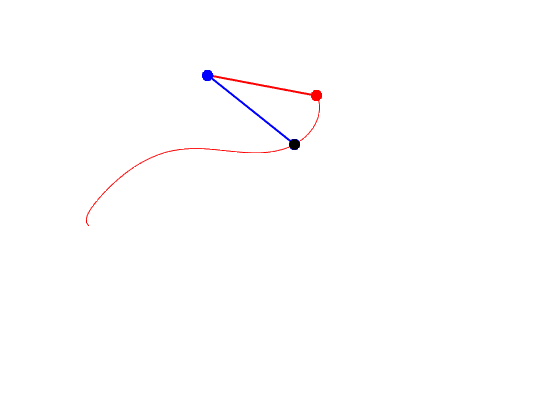

% Define pendulum parameters
theta1 = 2; theta2 = 2;
L1 = 1; L2 = 1;
m1 = 1 ; m2 =  1;
tmax = 10;
L = [L1, L2];
m = [m1, m2];

% Solve the differential equation
t = linspace(0, tmax, tmax * 60 + 1);
y0 = [theta1, theta2, 0, 0];
[t, theta] = ode45(@(t, y)doublependulum(t, y, L, m), t, y0);

% Calculate the (x, y) co-ordinates
x = zeros(length(t), 3);
y = zeros(length(t), 3);
for j = 1 : 2
    x(:, j + 1) = x(:, j) + L(j) * sin(theta(:, j));
    y(:, j + 1) = y(:, j) - L(j) * cos(theta(:, j));
end

% Plot pendulum
plotdoublependulum(t, x, y)

Here we no longer have the regular periodic motion that we saw with the single pendulum, instead the motion of the second weight follows a complicated path. Try experimenting with the various parameters to see what affects this has on the motion of the pendulum.

### Chaotic behaviour

What you may notice about the double pendulum is that slight changes in the initial parameters cause major changes to the motion of the pendulum. This can be seen more clearly below where the simulation has been run twice with the angle for $\theta_2$ in the second run of the simulation has been changed by a small amount (here it is `diff = 0.0001` which is equivalent to approximately 1/5000th of a degree).

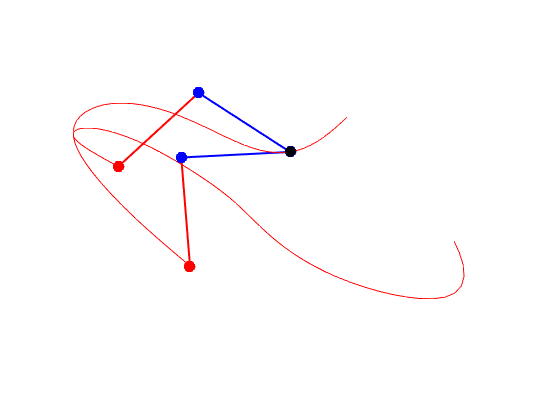

% Define pendulum parameters
diff =  0.0001;
theta1 = 2; theta2 = 2;
L1 = 1; L2 = 1;
m1 = 1 ; m2 =  1;
tmax = 10;
L = [L1, L2];
m = [m1, m2];

% Solve the differential equation
t = linspace(0, tmax, tmax * 60 + 1);
y0 = [theta1, theta2, 0, 0];
x = zeros(length(t), 6);
y = zeros(length(t), 6);
for i = 1 : 2
    y0(2) = y0(2) + diff;
    [t, theta] = ode45(@(t, y)doublependulum(t, y, L, m), t, y0);

    % Calculate the (x, y) co-ordinates
    for j = 1 : 2
        x(:, 3 * i + j - 2) = x(:, 3 * i + j - 3) + L(j) * sin(theta(:, j));
        y(:, 3 * i + j - 2) = y(:, 3 * i + j - 3) - L(j) * cos(theta(:, j));
    end

end

% Plot pendulum
plotdoublependulum(t, x, y)

See how after a few seconds the two solutions start to diverge. Even though the two pendulums started from very similar positions we get two very different solutions. This is what mathematicians call **chaotic behaviour** and gives rise to a branch of mathematics called chaos theory. This is also known as the **butterfly effect** after the notion that "*a butterfly flapping it's wings in Beijing can cause a storm in New York*".

## Modelling the motion of planets in a solar system

Another application of differential equations is the modelling of the motion of planets in a solar system.

### The 2-body problem

The simplest case we can consider is the motion of two bodies which is known as the 2-body problem. Consider the diagram below which shows two bodies in space. The two bodies are attracted to each other the gravitational force which means that body 1 is attracted to body 2 and body 2 is attracted to body 1. 

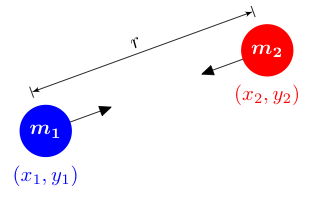

Newton discovered that the graviational force, $F$, acting between two bodies is related to their mass and the distance between them by the equation


$$F = G\frac{m_1m_2}{r^2},$$


where $G$ is a constant known as the **gravitational constant**. Since the masses of the two bodies are multiplied in the numerator (the top of the fraction), the larger mass of the bodies are the stronger the gravitational force. Also, the denominator (the bottom of the fraction) contains the squared distance between the the two bodies. If this distance is large then the fraction will have a small value so as the distance increases the gravitational force will decrease and vice-versa. This is the reason why our moon orbits the Earth despite the mass of the Sun being many times larger than that of the Earth. The distance between the moon and the Sun is too large to for the gravitational force to overcome that between the Earth and the moon.

If we let $u_1$ and $v_1$ be the velocities in the $x$ and $y$ directions for body 1 then we have the following differential equations that govern the velocity of body 1


$$\begin{array}{ll}
\frac{\mathrm{d}x_1}{\mathrm{d}t} &= u_1, &
\frac{\mathrm{d}y_1}{\mathrm{d}t} &= v_1.
\end{array}$$


Newton's second law of motion states that "*force is equal to mass times acceleration*" which, along with the equation for gravitational force, we can derive the following differential equations that govern the acceleration of body 1


$$\begin{array}{ll}
    \frac{\mathrm{d}u_1}{\mathrm{d}t} &= G \frac{m_2 (x_2 - x_1)}{r^3}, &
    \frac{\mathrm{d}v_1}{\mathrm{d}t} &= G \frac{m_2 (y_2 - y_1)}{r^3}
\end{array}$$


So we have 4 differential equations for the motion of body 1. Doing similar for body 2 gives us a system of 8 differential equations. 


$$\begin{array}{ll}
    \frac{\textrm{d}x_1}{\textrm{d}t} &= u_1, &
    \frac{\textrm{d}u_1}{\textrm{d}t} &= G \frac{m_2 (x_2 - x_1)}{r^3}, \\
    \frac{\textrm{d}y_1}{\textrm{d}t} &= v_1, &
    \frac{\textrm{d}v_1}{\textrm{d}t} &= G \frac{m_2 (y_2 - y_1)}{r^3}, \\
    \frac{\textrm{d}x_2}{\textrm{d}t} &= u_2, &
    \frac{\textrm{d}u_2}{\textrm{d}t} &= G \frac{m_1 (x_1 - x_2)}{r^3}, \\
    \frac{\textrm{d}y_2}{\textrm{d}t} &= v_2, &
    \frac{\textrm{d}v_2}{\textrm{d}t} &= G \frac{m_1 (y_1 - y_2)}{r^3}.
\end{array}$$


Don't worry if these equations look complicated, we can let the computer do all of the hard work of solving them. These equations have been defined in the code below and used to calculate the motion of two bodies in space. Body 1 has an initial position $(0, 0)$ and moving with initial velocity $(0, 0.4)$ and body 2 has an initial position $(1, 0)$ and moving with initial velocity $(0, -0.4)$. Both bodies have mass of $m_1=m_2=1$ and the gravitational constant is set to $G=1$. In reality gravitational force is incredibly weak and the gravitational constant is $G=0.00000000006674\text{ m$^3$kg$^{-1}$s$^{-2}$}$, this is why you can easily throw a ball in the air despite the mass of the Earth being so much more than the mass of the ball. 

% Define the position, velocities and masses of the bodies in the system
x1 = 0; y1 = 0;
x2 = 1; y2 = 0;
u1 = 0; v1 = 0.4;
u2 = 0; v2 = -0.4;
m1 = 1; m2 = 1;
global G
G = 1;
tmax = 5;
m = [m1, m2];

% Solve the differential equations
t = linspace(0, tmax, tmax * 100 + 1);
y0 = [x1, y1, x2, y2, u1, v1, u2, v2];
[t, y] = ode23s(@(t, y)nbody(t, y, m), t, y0);

% Plot solution
plotnbody(t, y)

Note how both bodies are attracted towards the other but their respective velocities means that they never collide and orbit each other. Try experimenting with changing the positions, velocities and masses of the two bodies to see what effects this has on their motion.

### The 3-body problem

global G
G = 1;

% Define the position, velocities and masses of the bodies in the system
x1 = 0;   y1 = 0;
x2 = -1;  y2 = 0;
x3 = 1;   y3 = 0;
u1 = 0;   v1 = 0;
u2 = 0;   v2 = 10;
u3 = 0;   v3 = -10;
m1 = 100; m2 = 1;   m3 = 1;
tmax = 5;
m = [m1, m2, m3];

% Solve the differential equations
t = linspace(0, tmax, tmax * 100 + 1);
y0 = [x1, y1, x2, y2, x3, y3, u1, v1, u2, v2, u3, v3];
[t, y] = ode23s(@(t, y)nbody(t, y, m), t, y0);

% Plot solution
plotnbody(t, y)

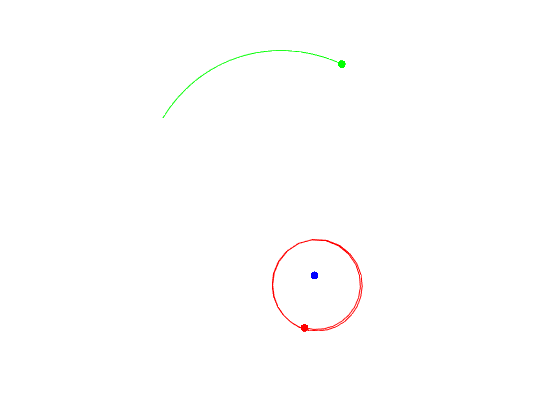

global G
G = 1;

% Define the position, velocities and masses of the bodies in the system
x1 = 0;   y1 = 0;
x2 = -1;  y2 = 0;
x3 = 1;   y3 = 0;
u1 = 0;   v1 = 0;
u2 = 0;   v2 = 10.5;
u3 = 0;   v3 = -10;
m1 = 100; m2 = 1;   m3 = 1;
tmax = 10;
m = [m1, m2, m3];

% Solve the differential equations
t = linspace(0, tmax, tmax * 100 + 1);
y0 = [x1, y1, x2, y2, x3, y3, u1, v1, u2, v2, u3, v3];
[t, y] = ode45(@(t, y)nbody(t, y, m), t, y0);

% Plot solution
plotnbody(t, y)

## Functions

function dtheta = pendulum(~, y, L)

g = 9.81;
theta = y(1);
dtheta(1) = y(2);
dtheta(2) = - g / L * sin(theta);
dtheta = dtheta';

end

function dtheta = doublependulum(~, y, L, m)

g = 9.81;
theta1 = y(1); theta2 = y(2);
dtheta(1:2) = y(3:4);
dtheta(3) = (-g * (2 * m(1) + m(2)) * sin(theta1) - m(2) * g * sin(theta1 - 2 * theta2) ...
    - 2 * sin(theta1 - theta2) * m(2) * (dtheta(2) ^ 2 * L(2) + dtheta(1) ^ 2 * L(1) ...
    * cos(theta1 - theta2))) / (L(1) * (2 * m(1) + m(2) - m(2) * cos(2 * theta1 - 2 * theta2)));
dtheta(4) = (2 * sin(theta1 - theta2) * (dtheta(1) ^ 2 * L(1) * (m(1) + m(2)) ...
    + g * (m(1) + m(2)) * cos(theta1) + dtheta(2) ^ 2 * L(2) * m(2) * cos(theta1 - theta2))) ...
    / (L(2) * (2 * m(1) + m(2) - m(2) * cos(2 * theta1 - 2 * theta2)));
dtheta = dtheta';

end

function dy = nbody(~, y, m)
   
global G
n = length(y) / 4;
dy = zeros(4 * n, 1);
dy(1 : 2 * n) = y(2 * n + 1 : end);
for i = 1 : n
    for j = setdiff(1 : n, i)
        xi = y(2 * i - 1);
        yi = y(2 * i);
        xj = y(2 * j - 1);
        yj = y(2 * j);
        r = sqrt((xi - xj) ^ 2 + (yi - yj) ^ 2);
        dy(2*n+2*i-1) = dy(2*n+2*i-1) + G * m(j) * (xj - xi) / r ^ 3;
        dy(2*n+2*i) = dy(2*n+2*i) + G * m(j) * (yj - yi) / r ^ 3;
    end
end

end

function plotpendulum(t, x, y, L)

clf
h1 = plot([0, x(1)], [0, y(1)], 'b-o', 'markersize', 20, 'markerfacecolor', 'b', 'linewidth', 2);
hold on
for i = 1 : 20
    h2(i) = plot(x(1), y(1), 'Color', 'b');
end
plot(0, 0, 'ko', 'markersize', 20, 'markerfacecolor', 'k');
hold off
axis equal off
axis([min(min(x)), max(max(x)), min(min(y)), max(0, max(max(y)))])

for i = 1 : length(t)
    set(h1, 'XData', [0, x(i)], 'YData', [0, y(i)]);
    for j = 1 : length(20)
        set(h2(j), 'XData', x(max(1, i - 50):i), 'YData', y(max(1, i - 50):i));
    end
    drawnow
end

end

function plotdoublependulum(t, x, y)

clf
N = size(x, 2) / 3;
hold on
h = [];
for i = 1 : N
    h = [h, plot(x(1, 3*i-1:3*i), y(1, 3*i-1:3*i), 'r-o', 'markersize', 10, 'markerfacecolor', 'r', 'linewidth', 2)];
    h = [h, plot(x(1, 3*i-2:3*i-1), x(1, 3*i-2:3*i-1), 'b-o', 'markersize', 10, 'markerfacecolor', 'b', 'linewidth', 2)];
    for j = 1 : 20
        h = [h, plot(x(1,2), y(1,2), 'Color', 'r')];
    end
end

plot(0, 0, 'ko', 'markersize', 10, 'markerfacecolor', 'k');
hold off
axis equal off
axis([min(min(x)), max(max(x)), min(min(y)), max(0, max(max(y)))])

for n = 1 : length(t)
    k = 1;
    for i = 1 : N
        set(h(k), 'XData', x(n, 3*i-1:3*i), 'YData', y(n, 3*i-1:3*i));
        set(h(k+1), 'XData', x(n, 3*i-2:3*i-1), 'YData', y(n, 3*i-2:3*i-1));
        k = k + 2;
        for j = 1 : 20
            set(h(k), 'XData', x(max(1,n-60):n, 3*i), 'YData', y(max(1,n-60):n, 3*i));
            k = k + 1;
        end
    end
    drawnow
end

end

function plotnbody(t, ysol)

clf 

% Extract x and y co-ordinates
N = size(ysol, 2) / 4;
x = ysol(:,1:2:2*N);
y = ysol(:,2:2:2*N);
fps = round(1 / (t(2) - t(1)));

% Create plot objects
col = ['b', 'r', 'g', 'k'];
h = [];
hold on 
for i = 1 : N
    h = [h, plot(x(1,i), y(1,i), '.', 'color', col(i), 'markersize', 20)];
    for j = 1 : 20
        h = [h, plot(x(1, i), y(1, i), '-', 'color', col(i))];
    end
end
hold off
axis equal off
axis([min(min(x)), max(max(x)), min(min(y)), max(max(y))]);

% Plot frames
for n = 1 : length(t)
    k = 1;
    for i = 1 : N
        set(h(k), 'XData', x(n, i), 'YData', y(n, i));
        k = k + 1;
        for j = 1 : 20
            set(h(k), 'XData', x(max(1,n-fps / 2):n, i), 'YData', y(max(1,n-fps / 2):n, i));
            k = k + 1;
        end
    end
    drawnow
end

end